# Linear Control Design II - Group Work Problem Module 14

## Description

Consider the airplane model (MIMO model).

% System matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0]

A =    -0.0558   -0.9968    0.0802    0.0415
    0.5980   -0.1150   -0.0318         0
   -3.0500    0.3880   -0.4650         0
         0    0.0805    1.0000         0


B = [0.00729 1e-5; -0.475 0.123; 0.153 1.063; 0 0]

B =     0.0073    0.0000
   -0.4750    0.1230
    0.1530    1.0630
         0         0


C = [0 1 0 0;0 0 0 1]

C =      0     1     0     0
     0     0     0     1


D = [0;0];

**Problem 1**

Is the system observable? Is it detectable?

% Fill in your answer here:
Mo = obsv(A,C);
rank(Mo)

ans = 4

**Problem 2**

In module 15 a multivariable state feedback controller for the aircraft was designed to assign the following closed-loop continuous eigenvalues


$$\lambda=\left\{\matrix{-0.5\cr-0.6\cr-0.5\pm0.5j}\right.$$


Design a discrete time observer for the system and use the sampling period $Ts=0.1\text{s}$. Find the observer gain matrix **L** that assigns the eigenvalues of the estimation error dynamics to be 4-5 times faster than those of the closed-loop system (in continuous time). Use the Matlab function *place()* and remember that an observer can be designed by solving the dual problem of controller design.

Check the eigenvalues of the estimation error.

% Fill in your answer here:
Ts = 0.1;
[F,G] = c2d(A,B,Ts)

F =     0.9902   -0.0985    0.0082    0.0041
    0.0597    0.9855   -0.0028    0.0001
   -0.2956    0.0525    0.9533   -0.0006
   -0.0147    0.0104    0.0977    1.0000


G =     0.0031   -0.0002
   -0.0472    0.0121
    0.0137    0.1041
    0.0005    0.0053


% observer design
lambda = [-0.5 -0.6 -0.5+0.5i -0.5-0.5i];
P_obsv_d = exp(5*lambda*Ts);
L = place(F',C',P_obsv_d)'

L =     0.1476   -0.4695
    0.3055   -0.1293
   -0.3282    1.3050
   -0.0252    0.5947


% verify the result
log(eig(F-L*C))/Ts

ans =   -2.5000 + 2.5000i
  -2.5000 - 2.5000i
  -2.5000 + 0.0000i
  -3.0000 + 0.0000i


**Problem 3**

Add the observer to the open loop Simulink model of the aircraft and carry out a simulation with the function on Figure 1 at both inputs, but one at a time. Plot the states, the state estimates and the estimation error.

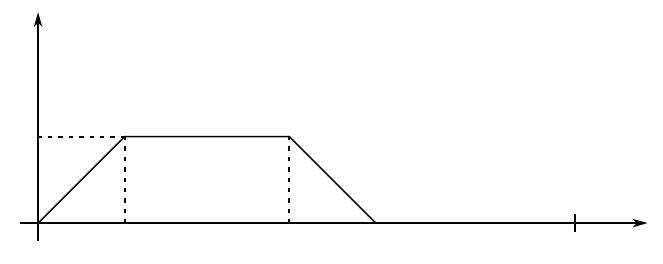


$$Figure\,1: Input\,signal\,for\,the\,closed\,loop\,system.$$


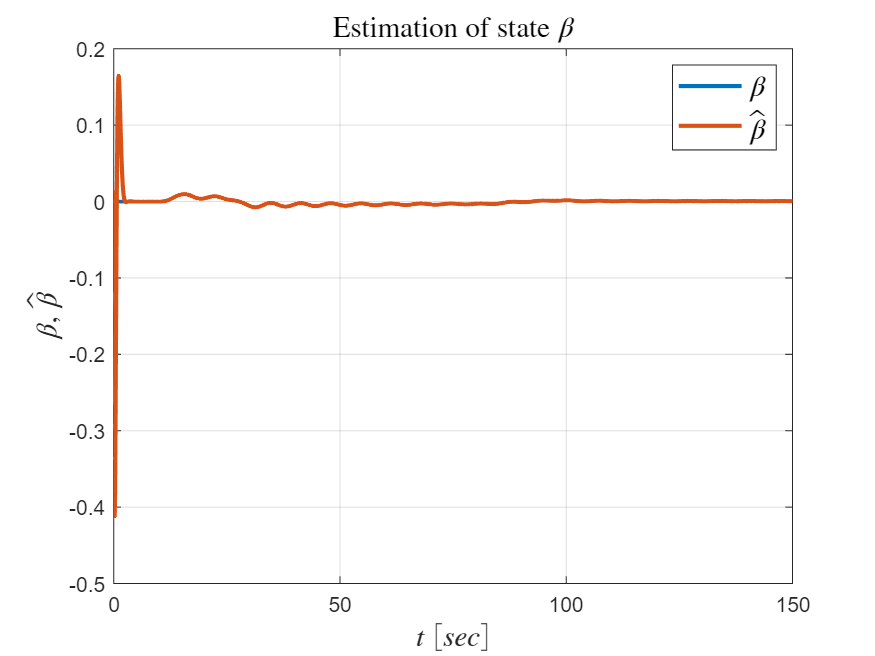

% Fill in your answer here:
t = 0:0.1:150;
t1 = 0:0.1:5;
r1 = 0.0175*t1/5;
r3 = -0.0175*t1/5+0.0175;
ra = [zeros(1,800) r1 0.0175*ones(1,99) r3 zeros(1,500)];
r = [zeros(1,100)  r1 0.0175*ones(1,99) r3 zeros(1,800) zeros(1,400)];

inp = [t' r' ra'];
x0 = [0;0;0;0];
x_esht_0 = [0.015;-0.03;-0.08;-0.7];
sim('MyobsvOpenLoopSimul', 150, [], inp);
%sim('obsvOpenLoopSimul');
%% Plots
t = states.time;

figure
plot(t,states.signals.values(:,[1,5]), 'LineWidth', 2)
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\beta, \; \hat{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$\beta$', '$\hat{\beta}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $\beta$', 'Interpreter', 'latex', 'FontSize', 14);
grid

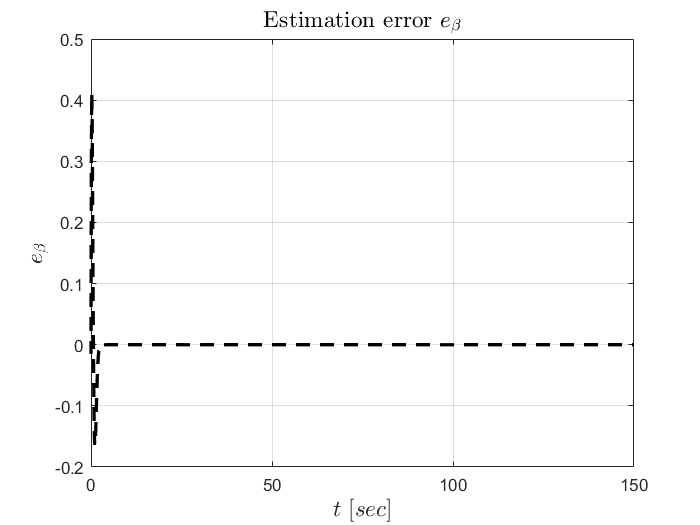

figure
plot(t,error.signals.values(:,1), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation error $e_{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
grid

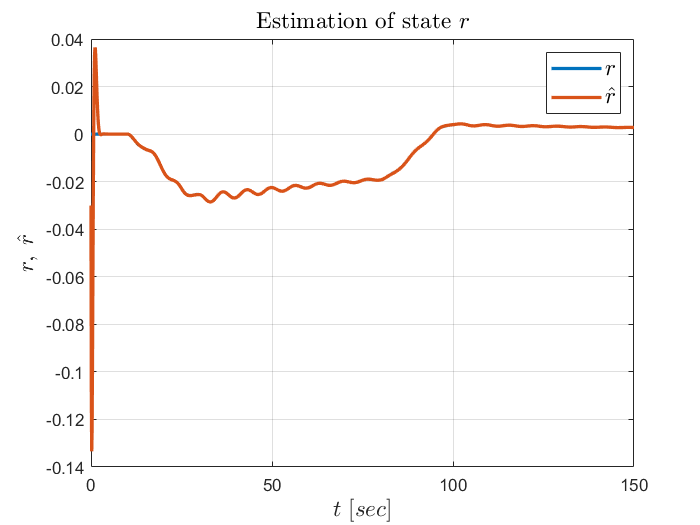

figure
plot(t,states.signals.values(:,[2,6]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$r, \; \hat{r}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$r$', '$\hat{r}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $r$', 'Interpreter', 'latex', 'FontSize', 14);
grid

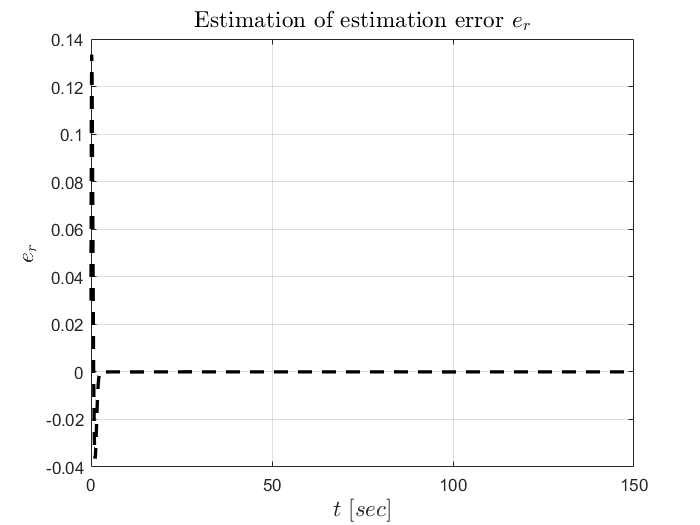

figure
plot(t,error.signals.values(:,2), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{r}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{r}$', 'Interpreter', 'latex', 'FontSize', 14);
grid

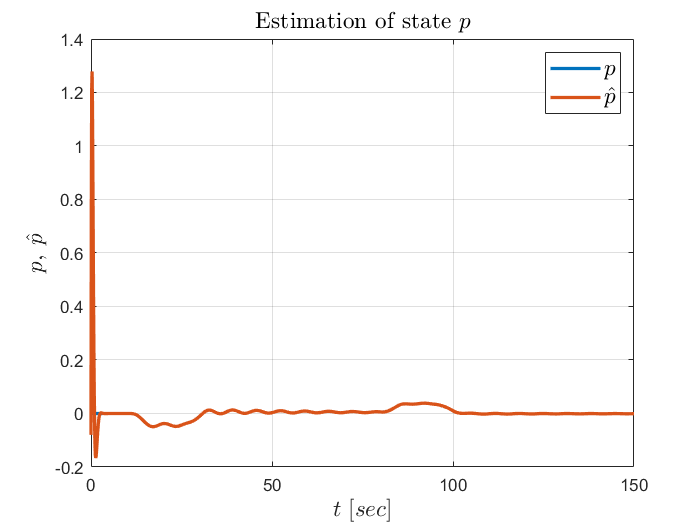

figure
plot(t,states.signals.values(:,[3,7]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$p, \; \hat{p}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$p$', '$\hat{p}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $p$', 'Interpreter', 'latex', 'FontSize', 14);
grid

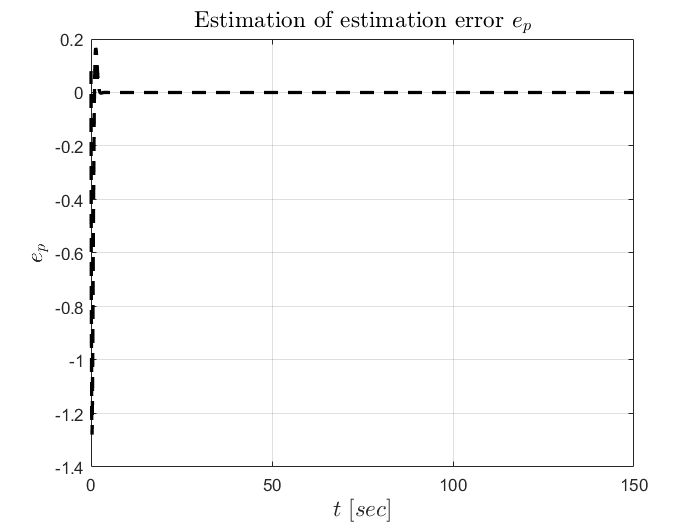

figure
plot(t,error.signals.values(:,3), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{p}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{p}$', 'Interpreter', 'latex', 'FontSize', 14);
grid

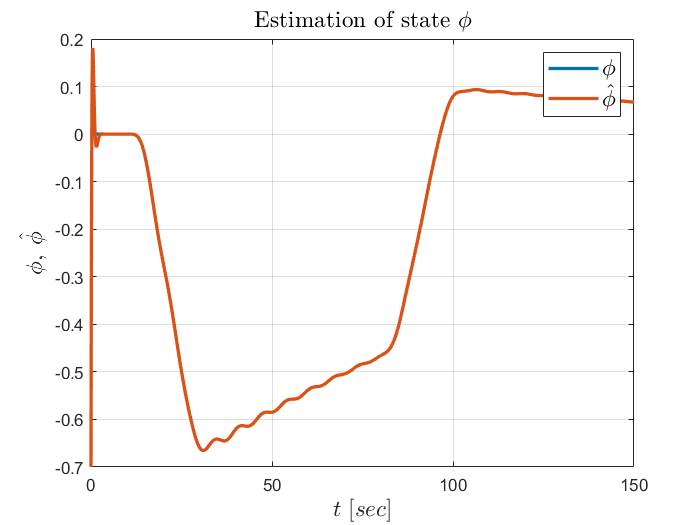

figure
plot(t,states.signals.values(:,[4,8]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\phi, \; \hat{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$\phi$', '$\hat{\phi}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $\phi$', 'Interpreter', 'latex', 'FontSize', 14);
grid

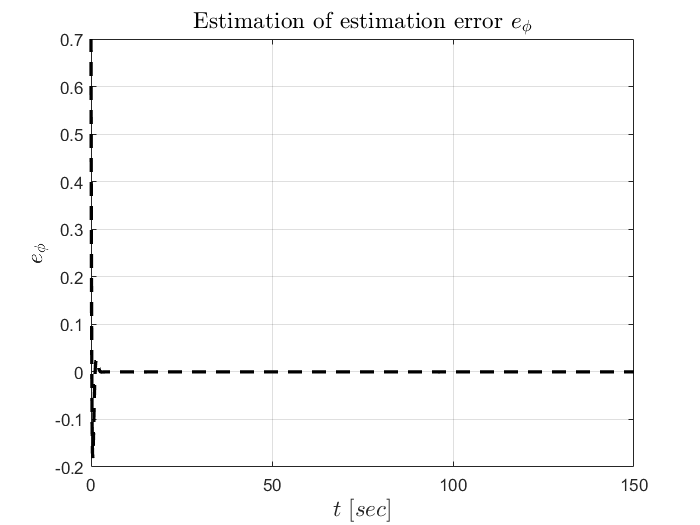

figure
plot(t,error.signals.values(:,4), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
grid

**Problem 4**

Add the discrete controller designed in the module 15 to the Simulink model and instead of using the true states of the system, use their estimates provided by the observer. Carry out simulations and plot the states, the state estimates, the estimation error, the outputs and the control signals. Compare the performance of the closed-loop systems with and without the observer.

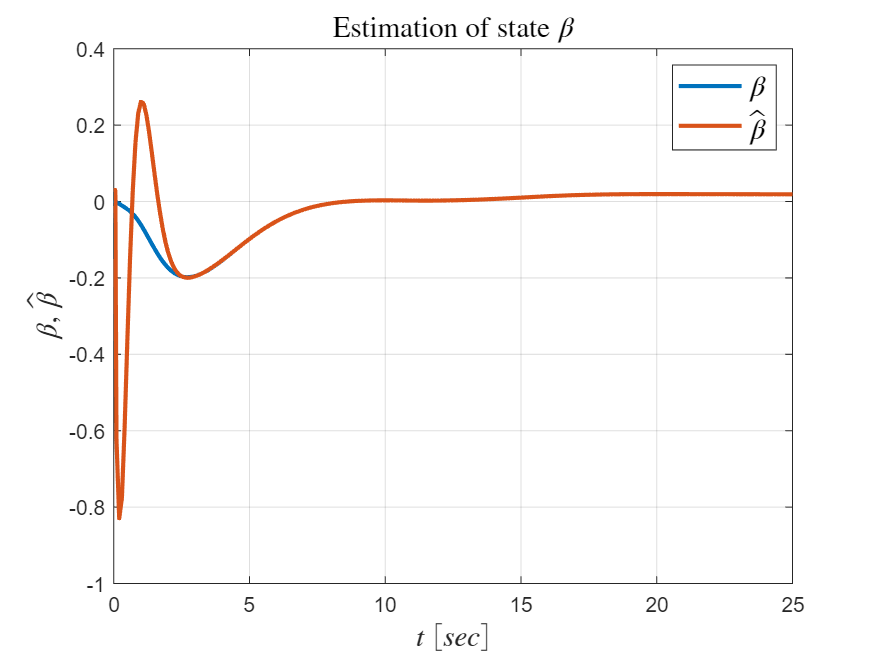

% Fill in your answer here:
% input reference
t=0:.1:150;
t1=0:.1:5;
r1=.0175*t1/5;
r3=.0175*(4-(t1+15)/5);
ra=[zeros(800,1)' r1 .0175*ones(99,1)' r3 zeros(1,500)];
r=[zeros(1,100) r1 .0175*ones(99,1)' r3 zeros(800,1)' zeros(1,400)];
inp = [t' r' ra'];

% feedback control gain
ev = [-0.5 -0.6 -0.5+0.5i -0.5-0.5i];
evd = exp(ev*Ts);
Kd = place(F,G,evd);

% initial states of system and obsv
x0 = [0;0;0;0];
x_esht_0 = [0.015;-0.03;-0.08;-0.7]*2;

sim('MyobsvCloseLoopSimul.slx',25,[],inp)

%% Plots
t = states.time;
figure;
plot(t,states.signals.values(:,[1,5]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\beta, \; \hat{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$\beta$', '$\hat{\beta}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $\beta$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

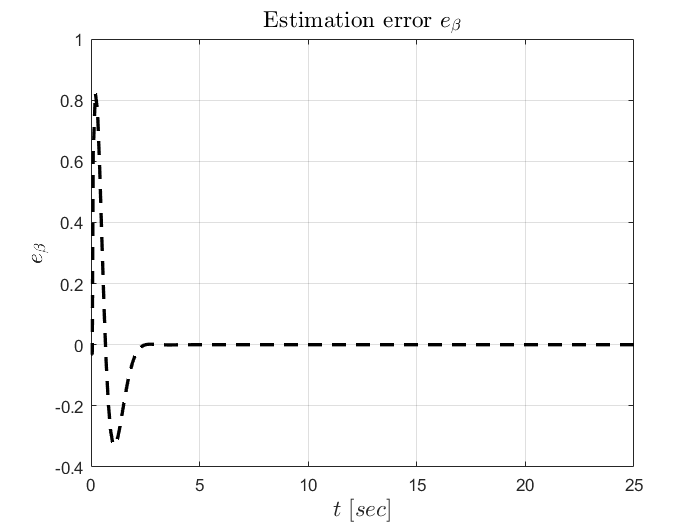

figure
plot(t,error.signals.values(:,1), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation error $e_{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

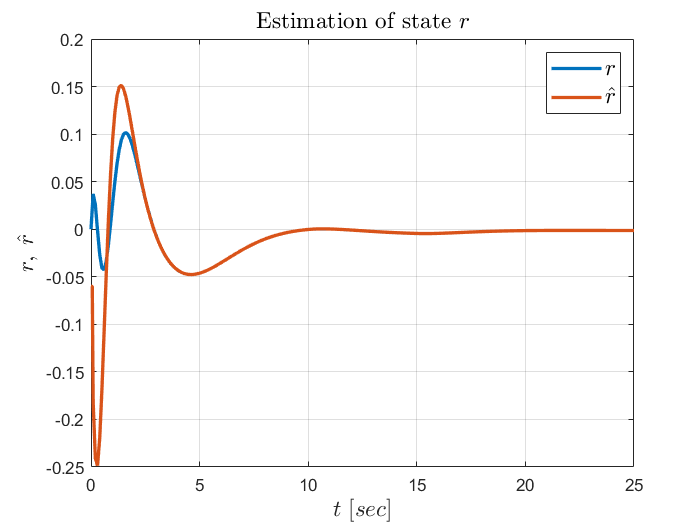

figure
plot(t,states.signals.values(:,[2,6]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$r, \; \hat{r}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$r$', '$\hat{r}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $r$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

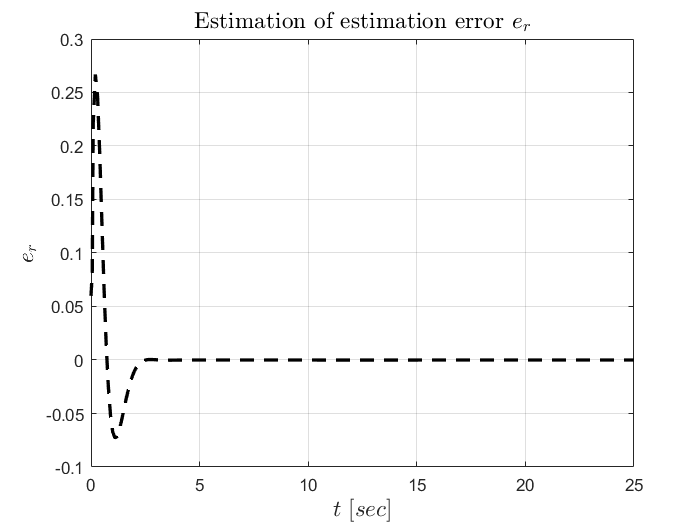

figure
plot(t,error.signals.values(:,2), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{r}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{r}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

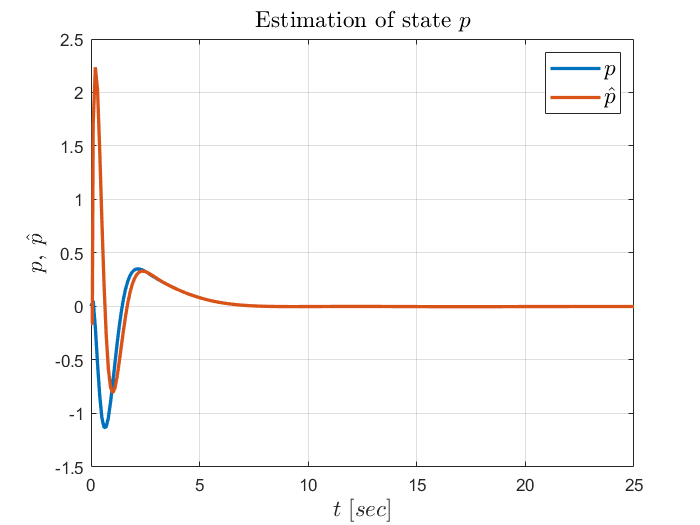

figure
plot(t,states.signals.values(:,[3,7]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$p, \; \hat{p}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$p$', '$\hat{p}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $p$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

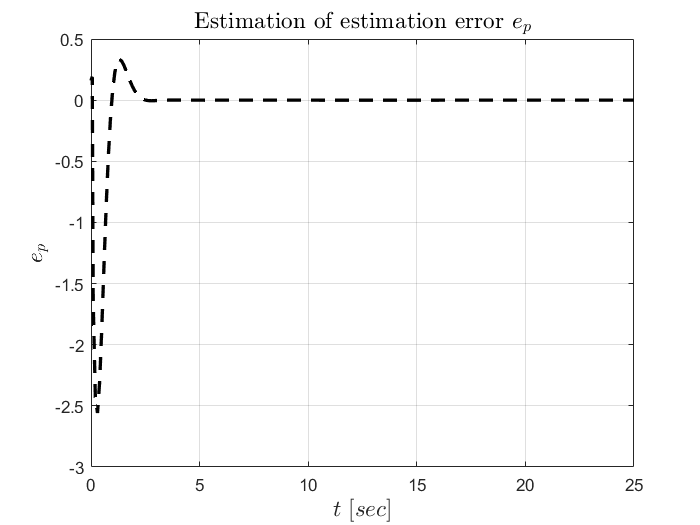

figure
plot(t,error.signals.values(:,3), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{p}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{p}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

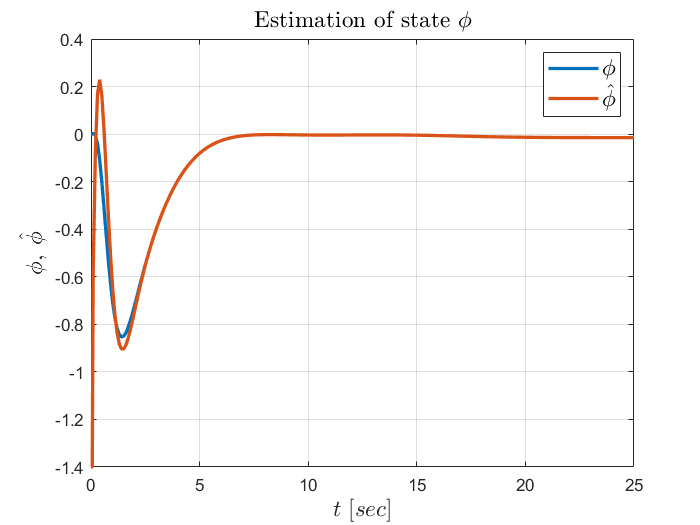

figure
plot(t,states.signals.values(:,[4,8]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\phi, \; \hat{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$\phi$', '$\hat{\phi}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $\phi$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

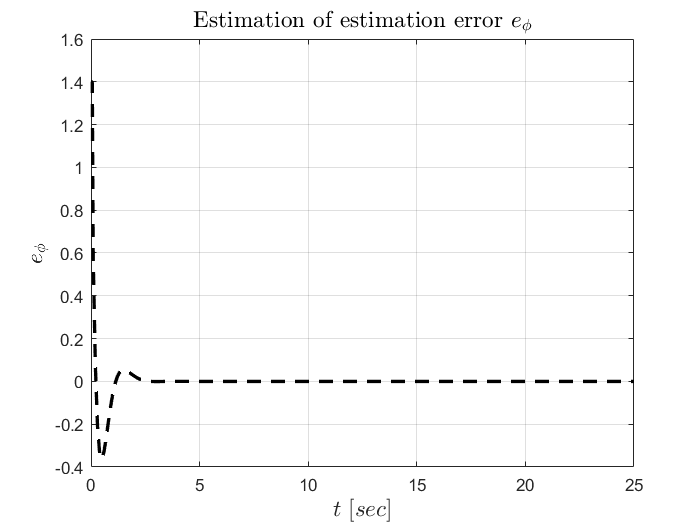

figure
plot(t,error.signals.values(:,4), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

**Problem 5**

Do the estimations obtained from the observer depend on how good the controller is? Can we estimate any of the states if the system is very fast or unstable?

% Fill in your answer here:



**Problem 6**

Repeat Problem 2-4 using the controller with integral action.

% Fill in your answer here:

% augment the system with integrators
Fi = [F zeros(4,2); -C eye(2,2)]

Fi =     0.9902   -0.0985    0.0082    0.0041         0         0
    0.0597    0.9855   -0.0028    0.0001         0         0
   -0.2956    0.0525    0.9533   -0.0006         0         0
   -0.0147    0.0104    0.0977    1.0000         0         0
         0   -1.0000         0         0    1.0000         0
         0         0         0   -1.0000         0    1.0000


Gi = [G; zeros(2,2)]

Gi =     0.0031   -0.0002
   -0.0472    0.0121
    0.0137    0.1041
    0.0005    0.0053
         0         0
         0         0


Ci = [C zeros(2,2)]

Ci =      0     1     0     0     0     0
     0     0     0     1     0     0



% design the controllers
ev1 = [-0.5 -0.6 -0.5+1i -0.5-1i  -0.7 -0.7];
ev1d = exp(ev1*Ts)

ev1d =    0.9512 + 0.0000i   0.9418 + 0.0000i   0.9465 + 0.0950i   0.9465 - 0.0950i   0.9324 + 0.0000i   0.9324 + 0.0000i


K1 = place(Fi,Gi,ev1d)

K1 =    11.5504    0.7679    1.1256    0.3606   -1.4904    0.0041
   27.0476    6.8870    1.7904   -0.3779   -3.4459    0.0583


Kd = K1(:,1:4)

Kd =    11.5504    0.7679    1.1256    0.3606
   27.0476    6.8870    1.7904   -0.3779


Ki = -K1(:,5:6)

Ki =     1.4904   -0.0041
    3.4459   -0.0583



% eigenvalue solution
cl_eval = 1/Ts*log(eig(Fi-Gi*K1))

cl_eval =   -0.5000 + 1.0000i
  -0.5000 - 1.0000i
  -0.5000 + 0.0000i
  -0.6000 + 0.0000i
  -0.7000 + 0.0000i
  -0.7000 + 0.0000i


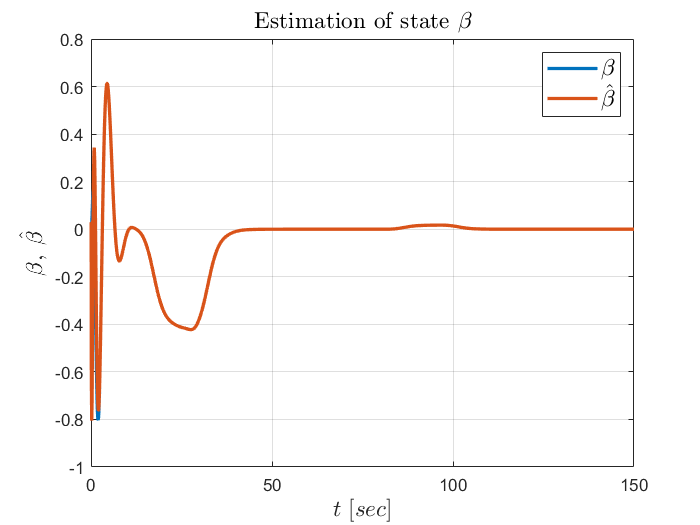


sim('MyobsvIntegralSimul.slx',150,[],inp);
%sim('obsvIntegralSimul.slx');
%% Plots
t = states.time;
figure;
plot(t,states.signals.values(:,[1,5]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\beta, \; \hat{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$\beta$', '$\hat{\beta}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $\beta$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

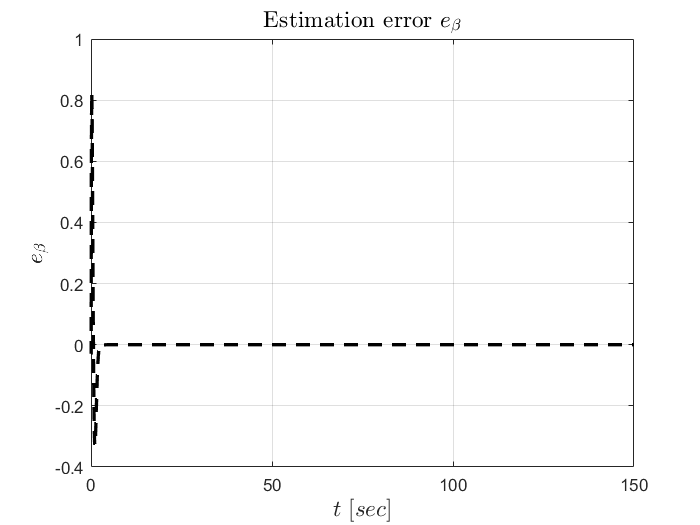

figure
plot(t,error.signals.values(:,1), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation error $e_{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

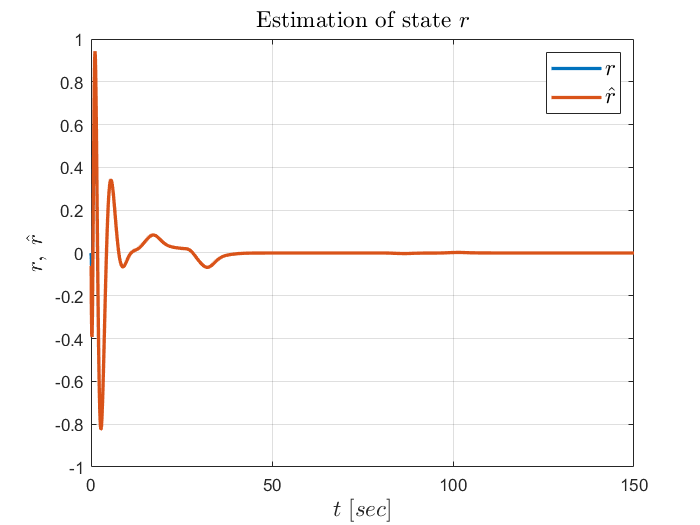

figure
plot(t,states.signals.values(:,[2,6]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$r, \; \hat{r}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$r$', '$\hat{r}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $r$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

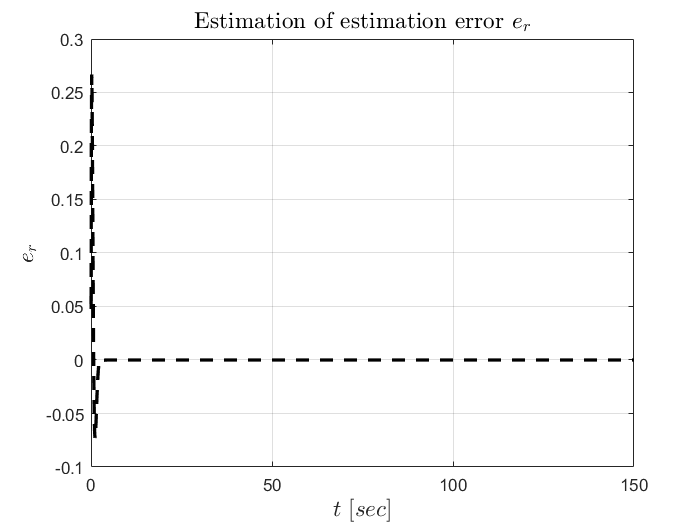

figure
plot(t,error.signals.values(:,2), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{r}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{r}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

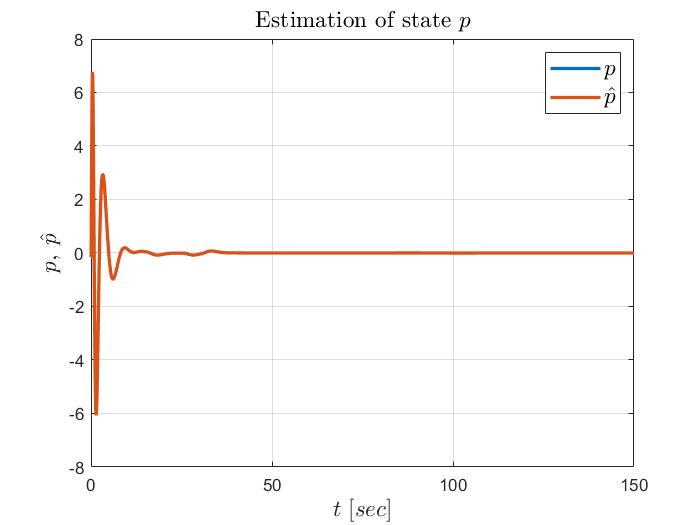

figure
plot(t,states.signals.values(:,[3,7]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$p, \; \hat{p}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$p$', '$\hat{p}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $p$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

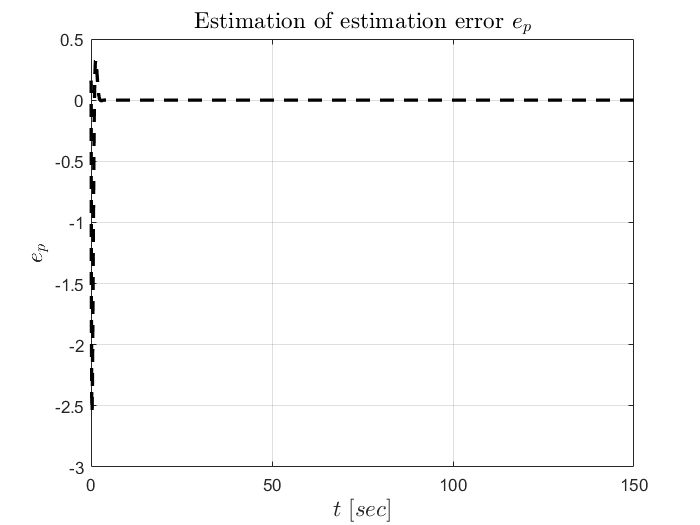

figure
plot(t,error.signals.values(:,3), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{p}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{p}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

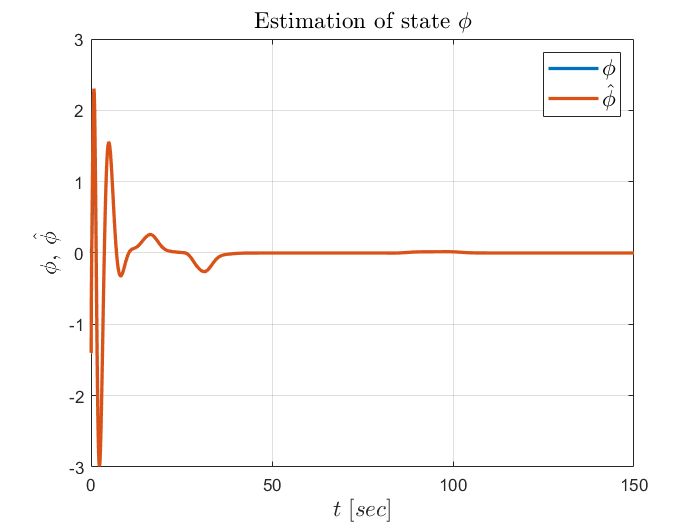

figure
plot(t,states.signals.values(:,[4,8]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\phi, \; \hat{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$\phi$', '$\hat{\phi}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $\phi$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

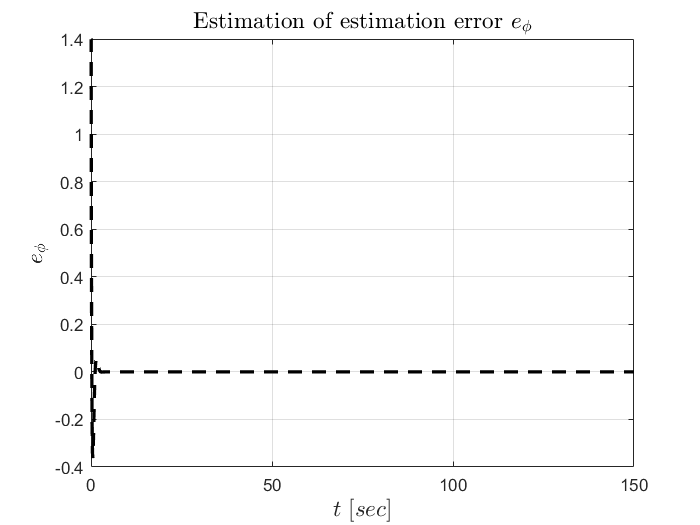

figure
plot(t,error.signals.values(:,4), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

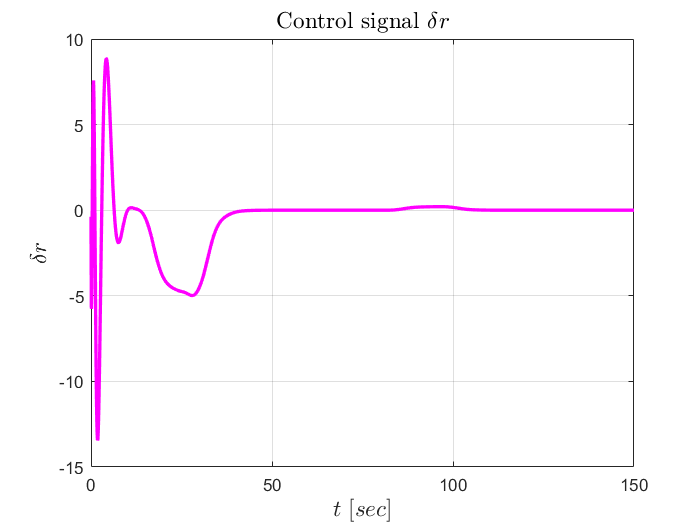


t = control.time;
figure
plot(t,control.signals.values(:,1), 'm', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\delta r$', 'Interpreter', 'latex', 'FontSize', 14);
title('Control signal $\delta r$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

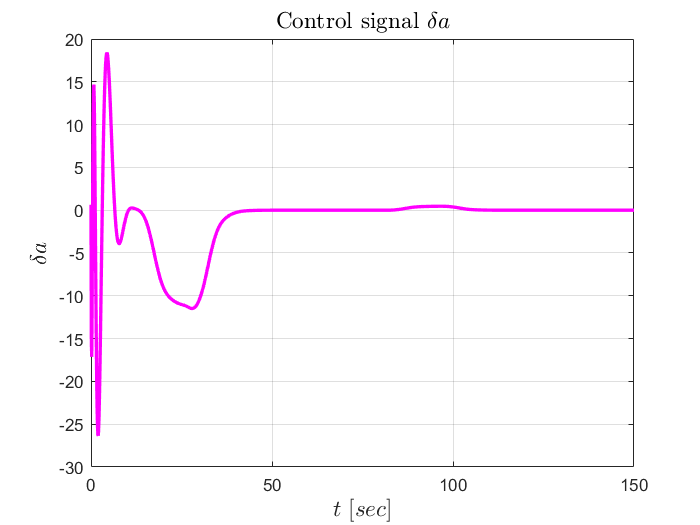

figure
plot(t,control.signals.values(:,2), 'm', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\delta a$', 'Interpreter', 'latex', 'FontSize', 14);
title('Control signal $\delta a$', 'Interpreter', 'latex', 'FontSize', 14);
grid;